# **Part 3**

A = [0 1 0;
  244.99991, -0.08677, 25.25359;
   0, 0, -250]

A =          0    1.0000         0
  244.9999   -0.0868   25.2536
         0         0 -250.0000



B = [0; 0; 5]

B =      0
     0
     5



C_s = [1 0 0]

C_s =      1     0     0



e = eig(A)

e =    15.6091
  -15.6959
 -250.0000


# **Part 4**

C_control = [B, A*B, ((A*A)*B)]

C_control = 	1.0e+05 *

         0         0    0.0013
         0    0.0013   -0.3158
    0.0001   -0.0125    3.1250


fprintf("Rank C: %d", rank(C_control))

Rank C: 3

O_observe = [C_s;  C_s*A ; C_s*A*A]

O_observe =     1.0000         0         0
         0    1.0000         0
  244.9999   -0.0868   25.2536


fprintf("Rank O: %d", rank(O_observe))

Rank O: 3

s = tf("s")

s =
 
  s
 
Continuous-time transfer function.



D = 0

G = C_s*(inv([s 0 0; 0 s 0; 0 0 s]-A))*B

G =
 
                 126.3
  ------------------------------------
  s^3 + 250.1 s^2 - 223.3 s - 6.125e04
 
Continuous-time transfer function.



# **Part 5**

syms S
%%PHI calculated without the inversion of the matrix and
% the laplace inverse in order to write on the report 
% with an easier format
Phi_s=[S 0 0; 0 S 0; 0 0 S]-A

$$Phi\_s = \left(\begin{array}{ccc} S & -1 & 0\\ -\frac{538760499698147}{2199023255552} & S+\frac{8677}{100000} & -\frac{7108253657110455}{281474976710656}\\ 0 & 0 & S+250 \end{array}\right)$$

%%the actual PHI calculated
Phi_t = ilaplace(inv([S 0 0; 0 S 0; 0 0 S]-A))

$$Phi\_t = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1}\,\left(\cosh\left(\sigma_{3}\right)+\sigma_{2}\right) & \frac{3276800000\,\sqrt{2}\,\sqrt{5261373426052311806923}\,\sigma_{1}\,\sinh\left(\sigma_{3}\right)}{5261373426052311806923} & \frac{177706341427761375\,{\mathrm{e}}^{-250\,t}}{437927970113058531968}-\frac{177706341427761375\,\sigma_{1}\,\left(\cosh\left(\sigma_{3}\right)-\frac{819057836032\,\sqrt{2}\,\sqrt{5261373426052311806923}\,\sinh\left(\sigma_{3}\right)}{5261373426052311806923}\right)}{437927970113058531968}\\ \frac{1683626561556709375\,\sqrt{2}\,\sqrt{5261373426052311806923}\,\sigma_{1}\,\sinh\left(\sigma_{3}\right)}{11033899803192457810512183296} & \sigma_{1}\,\left(\cosh\left(\sigma_{3}\right)-\sigma_{2}\right) & \frac{22213292678470171875\,\sigma_{1}\,\left(\cosh\left(\sigma_{3}\right)-\frac{14065291392091947\,\sqrt{2}\,\sqrt{5261373426052311806923}\,\sinh\left(\sigma_{3}\right)}{22067799606384915621024366592}\right)}{218963985056529265984}-\frac{22213292678470171875\,{\mathrm{e}}^{-250\,t}}{218963985056529265984}\\ 0 & 0 & {\mathrm{e}}^{-250\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{8677\,t}{200000}}\\ \sigma_{2}=\frac{142163968\,\sqrt{2}\,\sqrt{5261373426052311806923}\,\sinh\left(\sigma_{3}\right)}{5261373426052311806923}\\ \sigma_{3}=\frac{\sqrt{2}\,\sqrt{5261373426052311806923}\,t}{6553600000} \end{array}$$

# **Part 6**

b = [126.3]

b = 126.3000

a = [1 250.1 -223.3 -61250]

a = 	1.0e+04 *

    0.0001    0.0250   -0.0223   -6.1250


[z,p,k] = tf2zp(b,a)


z =

  0×1 empty double column vector



p =  -250.0133
   15.6087
  -15.6955


k = 126.3000

# **Part 7**

p = 1672.9094907742;
i = 6563.68389654975;
d = 104.927435464738;
n = 5549.0638

n = 5.5491e+03

C_s = p + i * (1/s) + d * ((n)/(1+(1/s)*n))

C_s =
 
  5.839e05 s^2 + 9.29e06 s + 3.642e07
  -----------------------------------
             s^2 + 5549 s
 
Continuous-time transfer function.



P_s = tf(b,a)

P_s =
 
                126.3
  ---------------------------------
  s^3 + 250.1 s^2 - 223.3 s - 61250
 
Continuous-time transfer function.



K_s = feedback(C_s*P_s,1)

K_s =
 
                  7.375e07 s^2 + 1.173e09 s + 4.6e09
  ------------------------------------------------------------------
  s^5 + 5799 s^4 + 1.388e06 s^3 + 7.245e07 s^2 + 8.334e08 s + 4.6e09
 
Continuous-time transfer function.



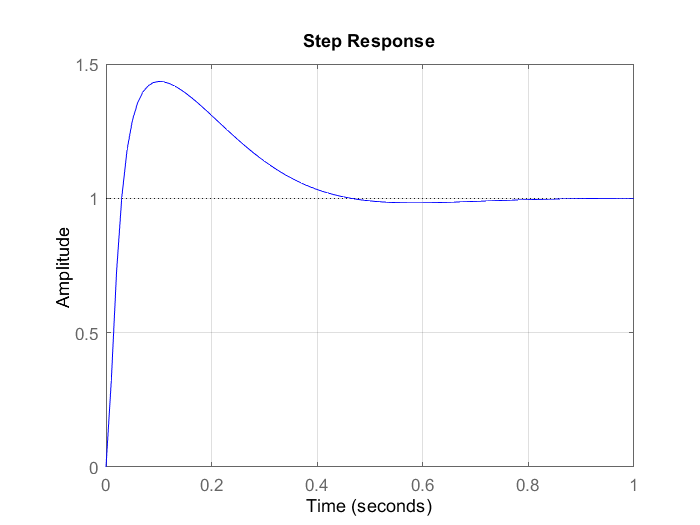


t = 0:0.01:1;
step(K_s,t,'b')
grid on